***Importar archivo Excel***

clear all

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 8);

% Specify sheet and range
opts.Sheet = "V4E_highres_2024-07-19,10h05m04";
opts.DataRange = "A2:H40001";

% Specify column names and types
opts.VariableNames = ["Identifier_Index", "ContactPoint_um_", "Hardness_MPa_", "ReducedMod__MPa_", "PosX_um_", "PosY_um_", "PosZ_um_", "Comment"];
opts.VariableTypes = ["string", "double", "double", "double", "double", "double", "double", "string"];

% Specify variable properties
opts = setvaropts(opts, ["Identifier_Index", "Comment"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Identifier_Index", "Comment"], "EmptyFieldRule", "auto");

% Import the data
excel_file = readtable("C:\Users\Asus\Desktop\V4E_highres_2024-07-19,10h05m04s.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
excel_file

excel_file = 40000×8 table
          Identifier_Index          ContactPoint_um_    Hardness_MPa_    ReducedMod__MPa_    PosX_um_    PosY_um_    PosZ_um_    Comment
    ____________________________    ________________    _____________    ________________    ________    ________    ________    _______

    "2024-07-16, 13:23:09, 7/0"          1.3825            8471.9            1.223e+05        17759         1953      3209.9       ""   
    "2024-07-16, 13:23:09, 7/1"          0.4884            8316.5           1.2226e+05        17759       1953.4      3209.9       ""   
    "2024-07-16, 13:23:09, 7/2"          0.4983            9265.5           1.3332e+05        17759       1953.8      3209.9       ""   
    "2024-07-16

Acondicionamiento del Excel: corregir posición estableciendo el 0, cambio de unidades de MPa a GPa, eliminar filas vacías

% Obtener el número de filas en tu tabla
num_filas = size(excel_file, 1);

% Inicializar el vector correct_PosZ
excel_file.PosZ = zeros(num_filas, 1);
excel_file.PosY= zeros(num_filas, 1);
excel_file.Hardness_GPa = zeros(num_filas, 1);
excel_file.ReducedMod_GPa = zeros(num_filas, 1);

% Iterar sobre cada fila y restar el último valor de esa fila
for i = 1:num_filas
    % Establecer el 0
    excel_file.PosZ(i) = round(excel_file.PosZ_um_(i) - excel_file.PosZ_um_(1),0); 
    excel_file.PosY(i) = round(excel_file.PosY_um_(i) - excel_file.PosY_um_(1),0);
    % MPa a GPa
    excel_file.Hardness_GPa(i) = excel_file.Hardness_MPa_(i).*10^-3;
    excel_file.ReducedMod_GPa(i) = excel_file.ReducedMod__MPa_(i).*10^-3;
end

rowswithNaN=isnan(excel_file.Hardness_MPa_) | isnan(excel_file.ReducedMod__MPa_);
cleandata=excel_file(~rowswithNaN,:);
% Eliminar la primera fila (encabezados)
cleandata(1, :) = [];

excel_file

excel_file = 40000×12 table
          Identifier_Index          ContactPoint_um_    Hardness_MPa_    ReducedMod__MPa_    PosX_um_    PosY_um_    PosZ_um_    Comment    PosZ    PosY    Hardness_GPa    ReducedMod_GPa
    ____________________________    ________________    _____________    ________________    ________    ________    ________    _______    ____    ____    ____________    ______________

    "2024-07-16, 13:23:09, 7/0"          1.3825            8471.9            1.223e+05        17759         1953      3209.9       ""        0       0         8.4719            122.3    
  

***Histogramas***

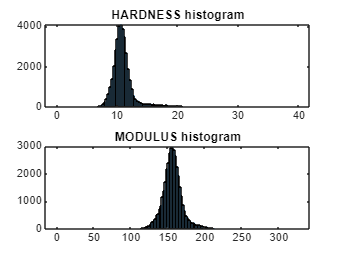

subplot(2,1,1)
histogram(cleandata.Hardness_GPa)
title("HARDNESS histogram")

subplot(2,1,2)
histogram(cleandata.ReducedMod_GPa)
title("MODULUS histogram")

***Contour plots***

% Ordenar X e Y en orden ascendente
Y_sorted = sort(unique(round(cleandata.PosY,0)));
Z_sorted = sort(unique(round(cleandata.PosZ,0)));

% Definir la cuadrícula para la interpolación
[z_grid, y_grid] = meshgrid(Z_sorted, Y_sorted);

% Interpolar HARDNESS
Z1_interpolated = griddata(cleandata.PosY, cleandata.PosZ, cleandata.Hardness_GPa, z_grid, y_grid, 'linear');


% Interpolar MODULUS
Z2_interpolated = griddata(cleandata.PosY, cleandata.PosZ, cleandata.ReducedMod_GPa, z_grid, y_grid, 'linear');

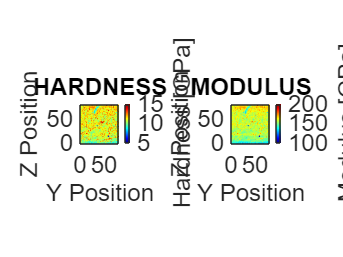


% Define the limit values of the hardness (1) and modulus (2) contour plots
vmin1 = 5;
vmax1 = 15;
vmin2 = 100;
vmax2 = 200;

% HARDNESS contour plot
subplot(1, 2, 1);

% Recortar los valores interpolados según vmin/vmax
Z1_matrix_clipped = min(max(Z1_interpolated, vmin1), vmax1);

% Crear el gráfico de contorno lleno (contourf)
contourf(Y_sorted, Z_sorted, Z1_matrix_clipped, 100,'LineStyle', 'none');

% Colocar la barra de color
cbar1 = colorbar;
cbar1.Label.String = 'Hardness [GPa]';
cbar1.Label.FontSize = 18;

% Modificar los límites de la colorbar
clim([vmin1, vmax1]); % Utiliza caxis para establecer los límites

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar1.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('Y Position', 'FontSize', 18);
ylabel('Z Position', 'FontSize', 18);

% Establecer el título del subplot
title('HARDNESS', 'FontSize', 18);

colormap('jet');

axis equal

% MODULUS contour plot
subplot(1, 2, 2);

% Recortar los valores interpolados según vmin/vmax
Z2_matrix_clipped = min(max(Z2_interpolated, vmin2), vmax2);

% Crear el gráfico de contorno lleno (contourf)
contourf(Y_sorted, Z_sorted, Z2_matrix_clipped, 100, 'LineStyle', 'none');

% Colocar la barra de color
cbar2 = colorbar;
cbar2.Label.String = 'Modulus [GPa]';
cbar2.Label.FontSize = 18;

% Modificar los límites de la colorbar
clim([vmin2, vmax2]); % Utiliza caxis para establecer los límites

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar2.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('Y Position', 'FontSize', 18);
ylabel('Z Position', 'FontSize', 18);

% Establecer el título del subplot
title('MODULUS', 'FontSize', 18);

colormap('jet');

axis equal